clear all
    for x=1:352
        for y=1:352
            fluxes{1000}{x}{y}{1}(1:95)=0;
        end
    end
flux_t1000

ac_up(1:352,1:352)=0;
ac_sec(1:352,1:352)=0;
ac_flux(1:352,1:352)=0;
ac(1:95)=0;
    for x=1:352
        for y=1:352
            ac(1:95)=0;
            ac=fluxes{1000}{x}{y}{1};
            %ac_flux(x,y)=ac(20);
            if ac(20)>0 
                ac_flux(x,y)=1;
            end
            if ac(20)<0 
                ac_flux(x,y)=-1;
            end
        end
    end

%C = [3 4 5; 1 2 5; 5 5 5];
%im=pcolor(ac_flux)
im=image(ac_flux(110:242,110:242),'CDataMapping','scaled')

im =   Image with properties:

           CData: [133×133 double]
    CDataMapping: 'scaled'

  Show all properties


%im=surf(ac_flux)
colormap(gca,parula);
x=[5 55];
y=[128 128];
line(x,y,'Color','black','LineWidth',5)
text(14,119,'5 mm','Color','black',"FontSize",25)

x=[5 10];
y=[10 10];
line(x,y,'Color','blue','LineWidth',10)
text(12,10,'acetate secretion','Color','black',"FontSize",12)

x=[5 10];
y=[20 20];
line(x,y,'Color','yellow','LineWidth',10)
text(12,20,'acetate uptake','Color','black',"FontSize",12)

text(80,10,'time = 2 days','Color','black',"FontSize",15)

%colorbar
%clim([0 0.05]);
%im.EdgeColor = 'none';
ax=gca;
ax.Box = 'off';
ax.XGrid = 'off';
ax.YGrid = 'off';
ax.ZGrid = 'off';
ax.XTick = [];
ax.YTick = [];
ax.ZTick = [];
ax.ZColor = 'none';
ax.YColor = 'none';
ax.XColor = 'none';
%colormap(ax,gray);
axis equal

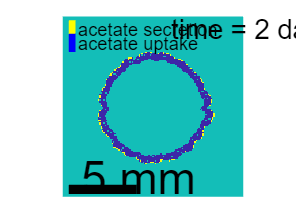

%saveas(gcf,'acetate_1000.png')
exportgraphics(gca,"acetate_1000.png",'Resolution', 300)